clear; clc; close all;

%Read in data
data = readmatrix("Sample_B.txt");
data(:,1) = [];
time = data(:,1);
waterTemp = data(:,2);
sampleTemp1 = data(:,3);
sampleTemp2 = data(:,4);
meanTemp = (sampleTemp1 + sampleTemp2)/2;
Cc = 0.895;
Ms = 39.3;
sigma_Ms = 0.001;
Mc = 510;
sigma_Mc = 0.05;

%Plot given data
figure
subplot(2,2,1);
hold on;
grid on;
plot(time, waterTemp, 'b-');
ylim([92 95]);
title("Water temperature vs. time");
xlabel("time (sec)");
ylabel("Temperature (^oC)");

subplot(2,2,2);
hold on;
grid on;
plot(time, sampleTemp1, 'r-');
plot(time, sampleTemp2, 'g-');
plot(time, meanTemp, 'k-');
title("Calorimeter temperature vs. time");
xlabel("time (sec)");
ylabel("Temperature (^oC)");
legend("First sample reading", "Second sample reading", "Average sample reading",'Location','best')

%Estimate important time stamps from data and find indices
timeAdded = 217.273; %Time sample is added
timeNoCurveLow = 276.583; %Time when the curve of the data starts noticeably
timeNoCurveHigh = 503.841; %Time when the curve of the data ends noticeably
sampleStart = find(time == timeAdded);
sampleNoCurveLow = find(time == timeNoCurveLow);
sampleNoCurveHigh = find(time == timeNoCurveHigh);

%Split up time vector
firstSection = time(1:sampleStart);
middleSection = time(sampleStart:sampleNoCurveLow);
lastSection = time(sampleNoCurveHigh:end);
curveSection = time(sampleNoCurveLow:sampleNoCurveHigh);

%Used to separate the curved section from the others
offsetX = 0;
offsetY = 0;

%Plot different sections together
subplot(2,2,4)
hold on;
grid on;
plot(firstSection, meanTemp(1:sampleStart));
plot(middleSection, meanTemp(sampleStart:sampleNoCurveLow));
plot(lastSection, meanTemp(sampleNoCurveHigh:end));
plot(curveSection+offsetX, meanTemp(sampleNoCurveLow:sampleNoCurveHigh)+offsetY);

%Least squares on first section
d = meanTemp(1:sampleStart);
Acol1 = firstSection;
Acol2 = ones(length(firstSection),1);
A = [Acol1 Acol2];

x_hat_1 = (A'*A)^-1*A'*d

x_hat_1 =    -0.0008
   23.7749


LeastSquares1 = @(x) x_hat_1(1)*x + x_hat_1(2);

%Plot regression line for first section
plot(firstSection, LeastSquares1(firstSection),'k--');

%Least squares on second section
e = meanTemp(sampleStart:sampleNoCurveLow);
Bcol1 = middleSection;
Bcol2 = ones(length(middleSection),1);
B = [Bcol1 Bcol2];

x_hat_2 = (B'*B)^-1*B'*e

x_hat_2 =     0.0567
   11.1349


LeastSquares2 = @(x)x_hat_2(1)*x + x_hat_2(2);

%Least squares on third section
f = meanTemp(sampleNoCurveHigh:end);
Ccol1 = lastSection;
Ccol2 = ones(length(lastSection),1);
C = [Ccol1 Ccol2];

x_hat_3 = (C'*C)^-1*C'*f

x_hat_3 =    -0.0004
   29.4064


LeastSquares3 = @(x)x_hat_3(1)*x + x_hat_3(2);

%Find the time and index where the second and third regressions intersect
intersectT = (x_hat_3(2)-x_hat_2(2))/(x_hat_2(1)-x_hat_3(1));

intersect = find((time < (intersectT+0.05)), 1, 'last' ); %Find max index

%Plot second and third regressions
plot(time(sampleStart:intersect), LeastSquares2(time(sampleStart:intersect)),'k--');
plot(time, LeastSquares3(time),'k--');

%Find T0, TH, and Tmid
T0 = LeastSquares1(time(sampleStart))

T0 = 23.5920

T1 = mean(waterTemp)

T1 = 93.4107

TH = LeastSquares3(time(sampleStart));
Tmid = (T0 + TH)/2

Tmid = 26.4522


%Find T2 by interpolating the second regression line
tMax = find((LeastSquares2(time) > Tmid), 1, 'first');
T2 = LeastSquares3(time(tMax))

T2 = 29.2894

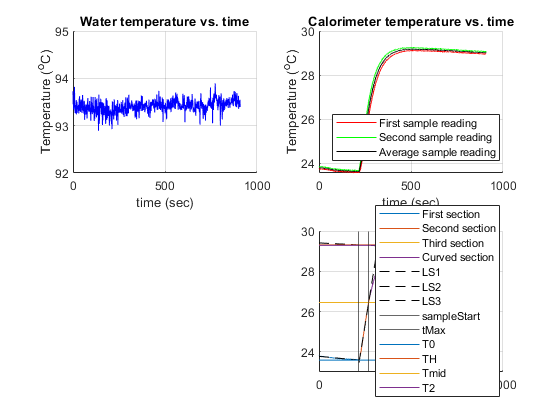


xline(time(sampleStart))
xline(time(tMax))
plot(time, T0*ones(length(time),1))
plot(time, TH*ones(length(time),1))
plot(time, Tmid*ones(length(time),1))
plot(time, T2*ones(length(time),1))

legend("First section","Second section","Third section","Curved section","LS1","LS2","LS3","sampleStart","tMax","T0","TH","Tmid","T2",'Location','best')
ylim([23 30])


%Find uncertainties
Cs = (Mc*Cc*(T2-T0))/(Ms*(T1-T2))

Cs = 1.0320


sigma_T1 = norm([2 std(waterTemp)]);
sigma_T2 = norm([2 std(LeastSquares3(lastSection))]);
sigma_T0 = norm([2 std(LeastSquares1(firstSection))]);

W1 = diag(1./sigma_T1.^2);
Q_line1 = (A'*W1*A)^-1;
sig_Y_T1 = norm([2 sqrt([sampleStart 1]*Q_line1*[sampleStart; 1])])

sig_Y_T1 = 2.0177


W2 = diag(1./sigma_T2.^2);
Q_line2 = (C'*W2*C)^-1;
sig_Y_T2 = norm([2 sqrt([tMax 1]*Q_line2*[tMax; 1])])

sig_Y_T2 = 2.0382


W3 = diag(1./sigma_T0.^2);
Q_line3 = (A'*W3*A)^-1;
sig_Y_T0 = norm([2 sqrt([sampleStart 1]*Q_line3*[sampleStart; 1])])

sig_Y_T0 = 2.0177


sigma_T1 = norm([2 std(waterTemp)])

sigma_T1 = 2.0040

sigma_T0 = norm([2 sqrt((sum((d-LeastSquares1(firstSection)).^2))/(length(firstSection)-2))])

sigma_T0 = 2.0001


sigTH = sqrt((sum((f-LeastSquares3(lastSection)).^2))/(length(lastSection)-2));
sigTmid = 0.5*norm([T0 TH]);

sigma_T2 = norm([2 sqrt((sum((f-LeastSquares3(lastSection)).^2))/(length(lastSection)-2))])

sigma_T2 = 2.0000


if sig_Y_T0 > sigma_T0
    sigma_T0 = sig_Y_T0;
end

if sig_Y_T1 > sigma_T1
    sigma_T1 = sig_Y_T1;
end

if sig_Y_T2 > sigma_T2
    sigma_T2 = sig_Y_T2;
end

sigma_Mc

sigma_Mc = 0.0500

sigma_Ms

sigma_Ms = 1.0000e-03

sigma_T0

sigma_T0 = 2.0177

sigma_T1

sigma_T1 = 2.0177

sigma_T2

sigma_T2 = 2.0382


sigma_Cs_Mc = (Cc*(T2-T0))/(Ms*(T1-T2))

sigma_Cs_Mc = 0.0020

sigma_Cs_T0 = -(Mc*Cc)/(Ms*(T1-T2))

sigma_Cs_T0 = -0.1811

sigma_Cs_Ms = -(Mc*Cc*(T2-T0))/((T1-T2)*(Ms)^2)

sigma_Cs_Ms = -0.0263

sigma_Cs_T2 = (Mc*Cc*(T1-T0))/(Ms*(T1-T2)^2)

sigma_Cs_T2 = 0.1972

sigma_Cs_T1 = -(Mc*Cc*(T2-T0))/(Ms*(T1-T2)^2)

sigma_Cs_T1 = -0.0161

sigma_Cs = Cs*sqrt((sigma_Cs_Mc*sigma_Mc)^2+(sigma_Cs_T0*sigma_T0)^2+(sigma_Cs_Ms*sigma_Ms)^2+(sigma_Cs_T2*sigma_T2)^2+(sigma_Cs_T1*sigma_T1)^2)

sigma_Cs = 0.5617


%sigma_Cs = ((Cs*Cc)/(Ms*(T1-T2)))*sqrt(((T2-T0)*sigma_Mc)^2+(-Mc*(T2-T0)*sigma_Mc/(Ms))^2+(-Mc*sigma_T0)^2+(-Mc*(T2-T0)*sigma_T1/(T1-T2))^2+(Mc*(T1-T0)*sigma_T2/(T1-T2))^2)

CsHigh = Cs + sigma_Cs

CsHigh = 1.5937

CsLow = Cs - sigma_Cs

CsLow = 0.4703


percentError = (0.261-Cs)/0.261

percentError = -2.9540